# Perceptron y Adaline sobre cada version del dato

Aqui se junta la revision de datos con los dos modelos del taller. Para cada dataset se toman las cinco tablas que dejaron R1 y R2 (crudo, sin outliers, balanceado, estandarizado, normalizado), se parte 70-30 con la misma semilla, y se entrena el perceptron y el Adaline sobre cada una. Asi se ve que paso del procesamiento le sirve a la neurona y cual no.

clear; close all; clc
if ~exist('informe/tablas', 'dir'), mkdir('informe/tablas'); end

pasos = {'T0_crudo', 'T1_outliers', 'T2_balanceado', 'T3_estandarizado', 'T4_normalizado'};

% parametros fijos para los dos modelos, iguales en todos los pasos
op_p = struct('regla', 3, 'alpha', 0.1,  'umbral', 0,   'salida', [-1 1], 'max_epocas', 200, 'semilla', 1);
op_a = struct('alpha', 0.01, 'umbral', 0.5, 'salida', [0 1], 'max_epocas', 500, 'semilla', 1);

## Iris

La neurona es una sola, asi que se arman dos problemas de dos clases: A) setosa contra las otras dos (se separa con una recta) B) versicolor contra virginica (no se separa del todo)

load iris_pasos.mat
vars = {'largo_sepalo', 'ancho_sepalo', 'largo_petalo', 'ancho_petalo'};
problemas = {'A: setosa vs resto', 'B: versicolor vs virginica'};

filas = {};
for pr = 1:2
    for k = 1:numel(pasos)
        T = eval(pasos{k});
        if pr == 1
            X = T{:, vars};  y = double(T.clase == 'setosa');
        else
            m = T.clase ~= 'setosa';
            X = T{m, vars};  y = double(T.clase(m) == 'versicolor');
        end
        [acc_p, ep_p, acc_a, ep_a] = entrenar_los_dos(X, y, op_p, op_a);
        filas(end+1, :) = {problemas{pr}, pasos{k}, ep_p, acc_p, ep_a, acc_a}; %#ok<SAGROW>
    end
end
R_iris = cell2table(filas, 'VariableNames', ...
    {'Problema', 'Paso', 'Epocas_perceptron', 'Exact_perceptron', 'Epocas_adaline', 'Exact_adaline'});
disp(R_iris)

               Problema                       Paso            Epocas_perceptron    Exact_perceptron    Epocas_adaline    Exact_adaline
    ______________________________    ____________________    _________________    ________________    ______________    _____________

    {'A: setosa vs resto'        }    {'T0_crudo'        }             2                   100              372                100    
    {'A: setosa vs resto'        }    {'T1_outliers'     }             2                   100              346                100    
    {'A: setosa vs resto'        }    {'T2_balanceado'   }             2                   100              346                100    
    {'A: setosa vs resto'        }    {'T3_estandarizado'}             2                   100               40                100    
    {'A: setosa vs resto'        }    {'T4_normalizado'  }             4                   100              500                100    
    {'B: versicolor vs virginica'}    {'T0_crudo'     

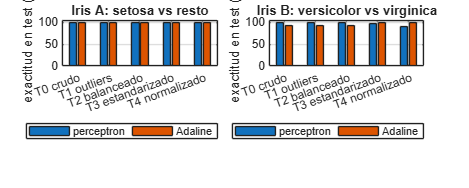

writetable(R_iris, 'informe/tablas/rev_iris_modelos.csv');

figure('Position', [100 100 950 380]);
for pr = 1:2
    subplot(1, 2, pr);
    m = strcmp(R_iris.Problema, problemas{pr});
    bar([R_iris.Exact_perceptron(m) R_iris.Exact_adaline(m)]); ylim([0 105]); grid on
    set(gca, 'XTickLabel', strrep(pasos, '_', ' '), 'XTickLabelRotation', 20);
    ylabel('exactitud en test (%)'); title(['Iris ' problemas{pr}]);
    legend({'perceptron', 'Adaline'}, 'Location', 'southoutside', 'Orientation', 'horizontal');
end
guardar_fig('rev_iris_modelos');

## Banknote

load banknote_pasos.mat
vars = {'varianza', 'asimetria', 'curtosis', 'entropia'};

filas = {};
for k = 1:numel(pasos)
    T = eval(pasos{k});
    X = T{:, vars};  y = double(T.clase == 'falso');
    [acc_p, ep_p, acc_a, ep_a, ec_a] = entrenar_los_dos(X, y, op_p, op_a);
    filas(end+1, :) = {pasos{k}, height(T), ep_p, acc_p, ep_a, ec_a, acc_a}; %#ok<SAGROW>
end
R_bank = cell2table(filas, 'VariableNames', ...
    {'Paso', 'Filas', 'Epocas_perceptron', 'Exact_perceptron', 'Epocas_adaline', 'EC_final_adaline', 'Exact_adaline'});
disp(R_bank)

            Paso            Filas    Epocas_perceptron    Exact_perceptron    Epocas_adaline    EC_final_adaline    Exact_adaline
    ____________________    _____    _________________    ________________    ______________    ________________    _____________

    {'T0_crudo'        }    1372            200                99.029                6               46.772             97.33    
    {'T1_outliers'     }    1372            200                98.786                6               32.089             97.33    
    {'T2_balanceado'   }    1220             43                98.907                6               29.365            95.902    
    {'T3_estandarizado'}    1220             23                 99.18                7               13.373            97.541    
    {'T4_normalizado'  }    1220             42                98.907              161               13.068            97.268    



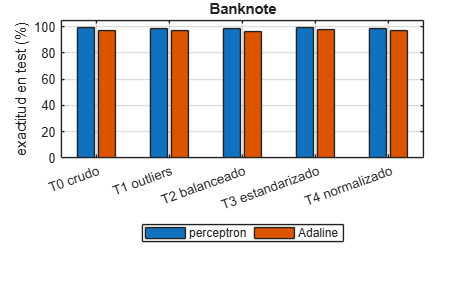

writetable(R_bank, 'informe/tablas/rev_banknote_modelos.csv');

figure('Position', [100 100 600 380]);
bar([R_bank.Exact_perceptron R_bank.Exact_adaline]); ylim([0 105]); grid on
set(gca, 'XTickLabel', strrep(pasos, '_', ' '), 'XTickLabelRotation', 20);
ylabel('exactitud en test (%)'); title('Banknote');
legend({'perceptron', 'Adaline'}, 'Location', 'southoutside', 'Orientation', 'horizontal');
guardar_fig('rev_banknote_modelos');

## Funcion local: parte 70-30, entrena los dos y devuelve exactitud en test

function [acc_p, ep_p, acc_a, ep_a, ec_a] = entrenar_los_dos(X, y, op_p, op_a)
    rng(2021)
    ind = randperm(numel(y));
    n_tr = round(0.7 * numel(y));
    tr = ind(1:n_tr);  te = ind(n_tr+1:end);

    % perceptron trabaja con salida en {-1, 1}
    d = 2*y - 1;
    [w, b, info] = perceptron(X(tr,:), d(tr), op_p);
    acc_p = 100 * mean(predecir(X(te,:), w, b, op_p.umbral, op_p.salida) == d(te));
    ep_p = info.epocas;

    % Adaline trabaja con salida en {0, 1}
    [w, b, info] = adaline(X(tr,:), y(tr), op_a);
    acc_a = 100 * mean(predecir(X(te,:), w, b, op_a.umbral, op_a.salida) == y(te));
    ep_a = info.epocas;
    ec_a = info.ec_final;
end